% This code was used to produce the numerical data in the paper on
% the rotational mobility of a spinning protein in a spherical membrane
% in the presence of external solvents of equal viscosity. This code 
% solves equations (19) and (20) in the paper by truncating the infinite
% sums at n=N_Modes (to be indicated by user) and solving the linear system
% (18) together with the condition v(x_p)=1. The code works as follows:

% (i) The code takes as inputs the number of c_n used (called 'N_Modes'), the
% dimensionless Saffman length 'epsilon' and the protein angle 'theta_p.' The
% code outputs the corresponding rotational mobility coefficient of the protein.

% (ii) The momentum equation (20) is solved by adding up N_Modes particular
% solutions of (1-x^2)v''(x)-4xv'(x)=P_n'(x) (1<=n<=N_Modes) and the homogeneous
% solution v=v_0 (constant), as the other homogeneous solution is not
% regular and x=-1 and hence has to be discarded. The particular solutions
% are stored in the symbolic vector V_n, whose k-th entry is the solution for n=k. The 
% truncated solution for v(x) is thus defined by N_modes+1 parameters, i.e.
% c_1,...,c_(N_Modes) and v_0

% (iii) The program goes on to substitute the expression for v(x) into (19),
% integrating symbolically up to the chosen protein angle x_p=cos theta_p
% yielding N_Modes linear equations for the c_k and v_0. For speed, we
% define a matrix called IntegralMatix whose i,j th entry (1<=i<=N_Modes+1
% and 1<=j<=N_Modes) is the integral V_i*P_(j-1)*(1-x^2) from -1 to x_p, and a
% vector CapIntegras whose i th entry (1<=i<=N_Modes) is the integral of P_(i-1)*(1-x^2) 
% from x_p to 1. The final equation is obtained by imposing v(x_p)=1. All calculations 
% are performed symbolically. At this stage, epsilon is specified as a symbolic variable
% so that, if we want to do this for a range of epsilon and theta, the
% complexity only scales with the range of theta. The resulting linear system is 
% then solved with vpasolve for the current values of theta_p and epsilon.

% (iv) The program outputs the torque needed to maintain the rotation,
% which can be found fro the rotlet coefficient c_1 as per Eq. (24) in the
% paper.

for i=1:301
i
load(['IntegralMatrix_' num2str(i) '.mat']);
IntegralMatrix(i,:)=vector; % Change
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

i = 146

i = 147

i = 148

i = 149

i = 150

i = 151

i = 152

i = 153

i = 154

i = 155

i = 156

i = 157

i = 158

i = 159

i = 160

i = 161

i = 162

i = 163

i = 164

i = 165

i = 166

i = 167

i = 168

i = 169

i = 170

i = 171

i = 172

i = 173

i = 174

i = 175

i = 176

i = 177

i = 178

i = 179

i = 180

i = 181

i = 182

i = 183

i = 184

i = 185

i = 186

i = 187

i = 188

i = 189

i = 190

i = 191

i = 192

i = 193

i = 194

i = 195

i = 196

i = 197

i = 198

i = 199

i = 200

i = 201

i = 202

i = 203

i = 204

i = 205

i = 206

i = 207

i = 208

i = 209

i = 210

i = 211

i = 212

i = 213

i = 214

i = 215

i = 216

i = 217

i = 218

i = 219

i = 220

i = 221

i = 222

i = 223

i = 224

i = 225

i = 226

i = 227

i = 228

i = 229

i = 230

i = 231

i = 232

i = 233

i = 234

i = 235

i = 236

i = 237

i = 238

i = 239

i = 240

i = 241

i = 242

i = 243

i = 244

i = 245

i = 246

i = 247

i = 248

i = 249

i = 250

i = 251

i = 252

i = 253

i = 254

i = 255

i = 256

i = 257

i = 258

i = 259

i = 260

i = 261

i = 262

i = 263

i = 264

i = 265

i = 266

i = 267

i = 268

i = 269

i = 270

i = 271

i = 272

i = 273

i = 274

i = 275

i = 276

i = 277

i = 278

i = 279

i = 280

i = 281

i = 282

i = 283

i = 284

i = 285

i = 286

i = 287

i = 288

i = 289

i = 290

i = 291

i = 292

i = 293

i = 294

i = 295

i = 296

i = 297

i = 298

i = 299

i = 300

i = 301

load('CapIntegrals.mat')
load('V_n_300.mat')


% Select the desired number of modes. Notice that smaller
% values of the protein angle require more modes to get accurate results. A
% good ballpark figure is N_Modes=|log(theta_p)|/theta_p^2. Computing time
% increases with N_Modes (50 modes take 1 mins, 100 take 11.5 mins).
% We start by resizing the symbolic arrays dependig on the number of modes.

N_Modes=100;
Truncated_IntegralMatrix=IntegralMatrix(1:(N_Modes+1),1:N_Modes);
Truncated_V_n=V_n(1:N_Modes);
Truncated_CapIntegrals=CapIntegrals(1:N_Modes);

syms x x_c v_0 v epsilon theta_c

% Define the symbolic arrays EquationVector (containing the N_Modes+1
% equations) and Ccoeffs (containing the c_n)
EquationVector = sym('E',[1 N_Modes+1],'real');
Ccoeffs = sym('C',[1 N_Modes],'real'); 

% We may now define v in terms of the V_n, the c_n, and the homogeneous
% solution v_0

% Insert the ranges of epsilon and theta to compute the mobility
% coefficient for.
epsilon_range=[0.1 0.25 0.5 1 2 100];
theta_range=0.1:0.1:3.1;


for theta_iteration=1:length(theta_range)
theta_iteration

thetac_value=sym(theta_range(theta_iteration));
xc_value=cos(thetac_value);

v=v_0+(epsilon/(2*thetac_value))*Truncated_V_n*diag(2*(1:N_Modes)+1)*Ccoeffs';

% For computational speed, we directly substitute xc_value into the
% equations and only leave epsilon as a symbolic variable

for i=1:N_Modes
i=sym(i) % Print iteration number so we know how far along we are
% We start by imposing the relation (18) for c_1,...,c_(N_Modes)
EquationVector(i)=i*(i+1)*Ccoeffs(i)/((2*i-1)*(2*i+1))-(i-1)*(i-2)*Ccoeffs((i-2)*double(i>=3)...
    +double(i<3))/((2*i-3)*(2*i-1))==v_0/2*subs(Truncated_IntegralMatrix(1,i),x_c,xc_value)+...
    (epsilon/(4*thetac_value))*subs(Truncated_IntegralMatrix(2:end,i),x_c, xc_value)'*...
    diag(2*(1:N_Modes)+1)*Ccoeffs'+(1/2)*subs(Truncated_CapIntegrals(i),x_c,xc_value); 
end
% The final condition comes from the velocity boundary condition at the
% inclusion edge
EquationVector(N_Modes+1)=subs(v,x,xc_value)==sym(1);

for IterationNumber=1:length(epsilon_range)
% Now we substitute the value of epsilon into the previously found system of equations
epsilon_value=sym(epsilon_range(IterationNumber));

[A,b] = equationsToMatrix(subs(EquationVector,epsilon,epsilon_value), [v_0, Ccoeffs]);
CValues=linsolve(vpa(A,200),vpa(b,200)); % Evaluate numerically for speed

% The torque can now be extracted from the rotlet coefficient
MobilityCoefficient=CValues(2)/thetac_value^3; 
filename=['MobCoeff' num2str(double(epsilon_value)) '_' num2str(double(thetac_value)) '_' num2str(double(N_Modes)) '.mat'];
save(filename,'N_Modes','MobilityCoefficient','CValues');
end
end

theta_iteration = 1

$$i = 1$$

$$i = 2$$

$$i = 3$$

$$i = 4$$

$$i = 5$$

$$i = 6$$

$$i = 7$$

$$i = 8$$

# Figure 3a, 3c

syms x
% Initialize parameters
%epsilon_value=5;
thetac_value=0.4;
N_Modes=100;
Meshsize=100; % Mesh where to plot the membrane velocity
% (from 0 to pi)
xc_value=cos(thetac_value);
%Truncated_V_n=V_n(1:N_Modes);
MembraneVelocity=CValues(2:end)'*diff(legendreP(1:N_Modes,x),x)';
Mesh=linspace(0,pi,Meshsize);
To_Plot=zeros(1,Meshsize);

for i=1:Meshsize
    To_Plot(i)=vpa(subs(MembraneVelocity,x,cos(Mesh(i))),1000);
end

clf
hold on
grid on
plot(Mesh,To_Plot.*sin(Mesh),'linewidth',4,'color','blue')
plot(Mesh,To_Plot,'linewidth',4,'color',[0.7 0 0.7])
xline(thetac_value,'--k','linewidth',1.5)
text(thetac_value+0.02,0.2,'$$\theta_p$$','Interpreter','latex','FontSize',20,'color','black')
text(1.3,0.85,'$$\varepsilon=5$$','Interpreter','latex','FontSize',20,'color','black')
text(1.85,0.2,'$$||\mathbf{v}||/R_m\Omega$$','Interpreter','latex','FontSize',20,'Color','blue')
text(1.8,0.57,'$$||\mathbf{v}||/R_m\Omega\sin\theta$$','Interpreter','latex','FontSize',20,'Color',[0.7 0 0.7])
%text(1.3,0.85,'$$\varepsilon=0.05$$','Interpreter','latex','FontSize',20,'color','black')

clear xticks
xticks(linspace(0,pi,5));
xticklabels({'$$0$$','$$\pi/4$$','$$\pi/2$$','$$3\pi/4$$','$$\pi$$'});
set(gca, 'XTick', xticks, 'XTickLabel', xticklabels)
hold off
ylim([0 1.02])
set(groot,'defaultAxesTickLabelInterpreter','latex');  
xlabel('$$\theta$$','Interpreter','latex','FontSize',20)
%ylabel('$$||\mathbf{v}||/R_m\Omega$$','Interpreter','latex','FontSize',20)
set(gca,'FontSize',20);

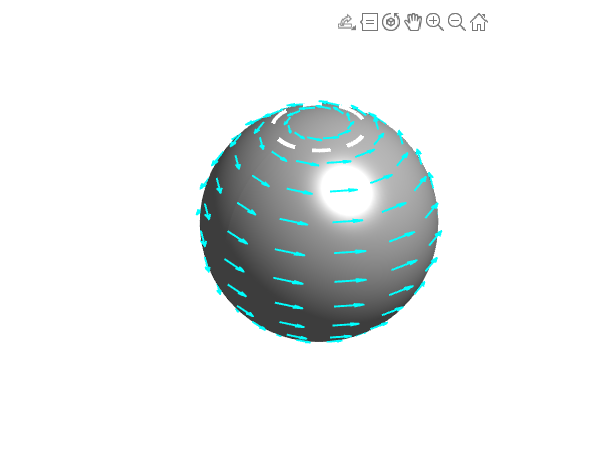

N_points=12;
[X Y Z]=sphere(N_points);
% maximum=sum(Z(:,1)<=cos(thetac_value));
% X=X(1:maximum,:);
% Y=Y(1:maximum,:);
% Z=Z(1:maximum,:);

v_phi=zeros(N_points+1,1);

for i=1:N_points+1 % compute the velocity field from the 
    v_phi(i)=vpa(subs(MembraneVelocity,x,Z(i,1)),1000)*sqrt(1-Z(i,1)^2);
end
e_phi_x=-Y./sqrt(X.^2+Y.^2);
e_phi_y=X./sqrt(X.^2+Y.^2);

U=e_phi_x.*v_phi;
V=e_phi_y.*v_phi;
W=e_phi_x*0;


clf
[X1 Y1 Z1]=sphere(100);
hs1=surf(X1,Y1,Z1);
set(hs1,'FaceColor',[0.8 0.8 0.8],'EdgeColor','none','FaceLighting','gouraud')
hold on
q1=quiver3(X,Y,Z,U,V,W,1,'LineWidth',1.3,'Color',[0 1 1],'MaxHeadSize',1,'AutoScale','off');
plot3(sin(thetac_value)*cos(linspace(0,2*pi,100)),...
    sin(thetac_value)*sin(linspace(0,2*pi,100)),cos(thetac_value)*ones(1,100),...
    '--','linewidth',3,'Color','white')
hold off
axis equal
axis off
camlight

# Figure 3b, 3d

% OUTER VELOCITY FIELD
theta_range=0.4; % Value of theta_range
X_max=5;
Z_max=5;
Gridsize=1000; % Number of mesh points on each side
[X,Z]=meshgrid(linspace(-X_max,X_max,Gridsize),linspace(-Z_max,Z_max,Gridsize)); 
% Grid around sphere. By axisymmetry, we only need to plot a slice of the flow. We pick the XZ
% plane.

R=(X.^2+Z.^2).^(1/2); % Spherical radius restricted to the plane Y=0. We assume WLOG that the cell has radius 1

Sin_Theta=abs(X).*R.^(-1);
Cos_Theta=Z.*(R.^(-1));
Outer_Velocity=zeros(Gridsize); % Component of outer velocity along the unit phi vector
CValues=double(CValues);

for i=1:40
Poly=double(coeffs(diff(legendreP(i,x),x),'All')); % Coefficients of P_i'(x), from ith to 0th power. Zero coefficients are included.
Outer_Velocity=Outer_Velocity+CValues(i+1)*(R.^(-i-1).*(R>1)+R.^(i).*(R<1)).*polyval(Poly,Cos_Theta).*Sin_Theta;
end

clf
hold on
imagesc(Outer_Velocity,'Interpolation','bilinear') % Blend in the pixels through fading
circle_centre=[500,500];
circle_radius=100;
tick_ratio=0.8;
viscircles(circle_centre, circle_radius,'Color','w','LineWidth',0.5);
plot(circle_centre+circle_radius*[tick_ratio*sin(theta_range),(2-tick_ratio)*sin(theta_range)],circle_centre+circle_radius*[tick_ratio*cos(theta_range),(2-tick_ratio)*cos(theta_range)],'LineWidth',1,'color','w');
plot(circle_centre-circle_radius*[tick_ratio*sin(theta_range),(2-tick_ratio)*sin(theta_range)],circle_centre+circle_radius*[tick_ratio*cos(theta_range),(2-tick_ratio)*cos(theta_range)],'LineWidth',1,'color','w');


% Stretch the colourbar to enhance gradients 
c0 = turbo(12800);
c1 = turbo(256); %create custom colourmap c1
for ci = 1:length(c1)
    cindex = round(tanh(ci/70)*length(c0));
    c1(ci,:) = c0(cindex,:);
end
colormap(c1); %this applies the modified colourmap
ax=gca;
ax.FontSize = 22;
axis square
axis tight
xlh=xlabel('$$x$$','Interpreter','Latex','FontSize',22);
ylh=ylabel('$$z$$','Interpreter','Latex','FontSize',22);
ylh.Position(1) = ylh.Position(1)+110; 
set(gca,'XTick',[])
ax1 = gca;
yruler = ax1.YRuler;
yruler.Axle.Visible = 'off';
xruler = ax1.XRuler;
xruler.Axle.Visible='off';
xticks(linspace(1,1000,3));
xticklabels({'$$-5$$','$$0$$','$$5$$'});
set(gca, 'XTick', xticks, 'XTickLabel', xticklabels)
yticks(linspace(1,1000,3));
ax1.XAxis.TickLength = [0 0];
ax1.YAxis.TickLength = [0 0];
yticklabels({'$$-5$$','$$0$$','$$5$$'});
set(gca, 'YTick', yticks, 'YTickLabel', yticklabels)
text(800,1050,'$$||\mathbf V^{\pm}||/R_m\Omega$$','Interpreter','latex','FontSize',20);

c=colorbar('EastOutside','TickLabelInterpreter', 'latex');
c.FontSize=20;
set(gca,'dataAspectRatio',[1 1 1])
hold off

# Figure 4 

Load Torque_vs_Angle

N_Modes=100; % Fixed 100
epsilon_range=[0.1, 0.25, 0.5, 1, 2, 100];
theta_range=0.1:0.1:3.1;

% Initialise mesh
Values_To_Plot=zeros(1,length(theta_range));
colours=hot(1000);
colours=colours(floor(linspace(200,450,6))',:);

clf
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
hold on
for i=1:length(epsilon_range)
    % Smaller angles are compute with more modes, so we load them
    % separately
    
    % load(['MobCoeff' num2str(epsilon_range(i)) '_' num2str(theta_range(1)) '_' num2str(double(300)) '.mat'],'MobilityCoefficient');
    % Values_To_Plot(1)=MobilityCoefficient*theta_range(1)^3;
    % load(['MobCoeff' num2str(epsilon_range(i)) '_' num2str(theta_range(2)) '_' num2str(double(200)) '.mat'],'MobilityCoefficient');
    % Values_To_Plot(2)=MobilityCoefficient*theta_range(2)^3;
    % load(['MobCoeff' num2str(epsilon_range(i)) '_' num2str(theta_range(3)) '_' num2str(double(200)) '.mat'],'MobilityCoefficient');
    % Values_To_Plot(3)=MobilityCoefficient*theta_range(3)^3;
  
    for j=1:length(theta_range)
    load(['MobCoeff' num2str(epsilon_range(i)) '_' num2str(theta_range(j)) '_' num2str(double(N_Modes)) '.mat'],'MobilityCoefficient','CValues');
    Values_To_Plot(j)=MobilityCoefficient*theta_range(j)^3;
    end
    plot([0 theta_range],[0 Values_To_Plot],'color',colours(i,:),'linewidth',4)
end
annotation('arrow', [0.3 0.52], [0.8 0.52],'linewidth',1)
hold off
xlim([0,pi])
ylim([0,1.05])
xticks(linspace(0,pi,5));
xticklabels({'$$0$$','$$\pi/4$$','$$\pi/2$$','$$3\pi/4$$','$$\pi$$'});
set(gca, 'XTick', xticks, 'XTickLabel', xticklabels)
text(1.3,0.43,'increasing $$\varepsilon$$','Interpreter','latex','fontsize',20)
xlabel('$$\theta_p$$','Interpreter','latex','FontSize',20)
ylabel('$$G_p/G_m$$','Interpreter','latex','FontSize',20)
ax=gca;
ax.FontSize = 20;
grid on
set(groot,'defaultLegendInterpreter','latex');
lgd=legend('$$0.1$$','$$0.25$$', '$$0.5$$', '$$1$$', '$$2$$', '$$100$$','interpeter','latex','location','southeast');

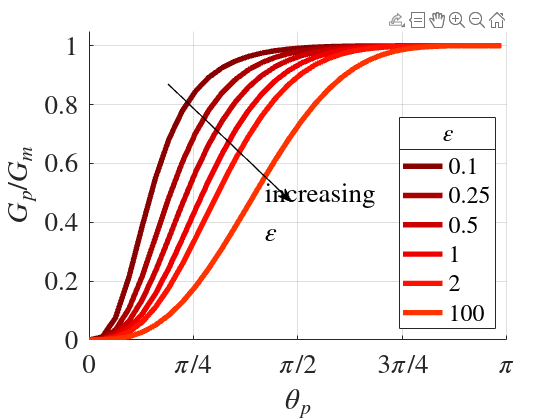

title(lgd,'$$\varepsilon$$','Interpreter','latex');
colours=hot(1000);
colours=colours(200:500,:);
colormap(colours)

N_Modes=100; % Fixed 100
epsilon_range=[0.1, 0.25, 0.5, 1, 2, 100];
theta_range=0.1:0.1:1.6;

% Initialise mesh
Values_To_Plot=zeros(1,length(theta_range));
colours=hot(1000);
colours=colours(floor(linspace(200,450,6))',:);

clf
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
hold on
for i=1:length(epsilon_range)
    % Smaller angles are compute with more modes, so we load them
    % separately
    
    % load(['MobCoeff' num2str(epsilon_range(i)) '_' num2str(theta_range(1)) '_' num2str(double(300)) '.mat'],'MobilityCoefficient');
    % Values_To_Plot(1)=MobilityCoefficient*theta_range(1)^3;
    % load(['MobCoeff' num2str(epsilon_range(i)) '_' num2str(theta_range(2)) '_' num2str(double(200)) '.mat'],'MobilityCoefficient');
    % Values_To_Plot(2)=MobilityCoefficient*theta_range(2)^3;
    % load(['MobCoeff' num2str(epsilon_range(i)) '_' num2str(theta_range(3)) '_' num2str(double(200)) '.mat'],'MobilityCoefficient');
    % Values_To_Plot(3)=MobilityCoefficient*theta_range(3)^3;
  
    for j=1:length(theta_range)
    load(['MobCoeff' num2str(epsilon_range(i)) '_' num2str(theta_range(j)) '_' num2str(double(N_Modes)) '.mat'],'MobilityCoefficient','CValues');
    Values_To_Plot(j)=MobilityCoefficient*theta_range(j)^3/(1-CValues(2));
    end
    plot([0 theta_range],[0 Values_To_Plot],'color',colours(i,:),'linewidth',4)
end
annotation('arrow', [0.3 0.52], [0.8 0.52],'linewidth',1)
hold off

text(1.3,0.43,'increasing $$\varepsilon$$','Interpreter','latex','fontsize',20)
xlabel('$$\theta_p$$','Interpreter','latex','FontSize',20)
ylabel('$$G_p/\tilde G_m$$','Interpreter','latex','FontSize',20)
xticks(linspace(0,pi,5));
xticklabels({'$$0$$','$$\pi/4$$','$$\pi/2$$','$$3\pi/4$$','$$\pi$$'});
set(gca, 'XTick', xticks, 'XTickLabel', xticklabels)
ax=gca;
ax.FontSize = 20;
grid on
set(groot,'defaultLegendInterpreter','latex');
lgd=legend('$$0.1$$','$$0.25$$', '$$0.5$$', '$$1$$', '$$2$$', '$$100$$','interpeter','latex','location','southeast');

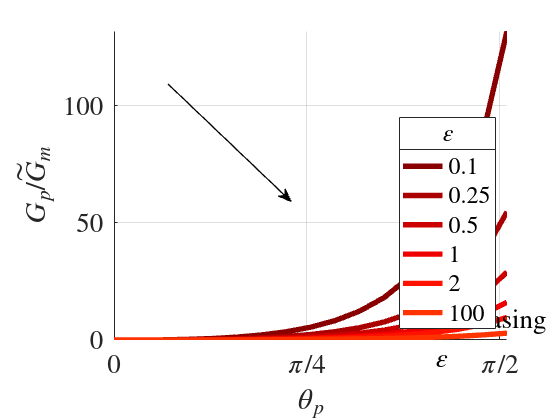

title(lgd,'$$\varepsilon$$','Interpreter','latex');
colours=hot(1000);
colours=colours(200:500,:);
colormap(colours)
axis tight

# Figure 5a

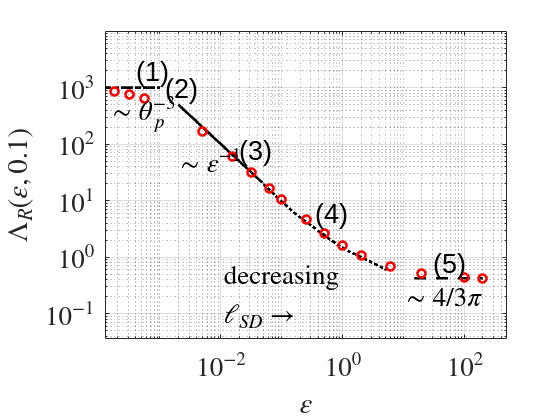

Mobilities=zeros(1,13);
load('MobCoeff0.015625_0.1_300.mat');
Mobilities(1)=MobilityCoefficient;
load('MobCoeff0.005_0.1_300.mat');
Mobilities(2)=MobilityCoefficient;
load('MobCoeff0.03125_0.1_300.mat');
Mobilities(3)=MobilityCoefficient;
load('MobCoeff0.0625_0.1_300.mat');
Mobilities(4)=MobilityCoefficient;
load('MobCoeff0.1_0.1_300.mat');
Mobilities(5)=MobilityCoefficient;
%load("MobCoeff0.125_0.1_300.mat");
%Mobilities(5)=MobilityCoefficient;
load('MobCoeff0.25_0.1_300.mat');
Mobilities(6)=MobilityCoefficient;
load('MobCoeff0.5_0.1_300.mat');
Mobilities(7)=MobilityCoefficient;
load('MobCoeff1_0.1_300.mat');
Mobilities(8)=MobilityCoefficient;
load('MobCoeff2_0.1_300.mat');
Mobilities(9)=MobilityCoefficient;
load('MobCoeff6_0.1_300.mat');
Mobilities(10)=MobilityCoefficient;
load('MobCoeff20_0.1_300.mat');
Mobilities(11)=MobilityCoefficient;
load('MobCoeff100_0.1_300.mat');
Mobilities(12)=MobilityCoefficient;
load('MobCoeff200_0.1_300.mat')
Mobilities(13)=MobilityCoefficient;
load('MobCoeff0.00017783_0.1_300.mat')
Mobilities(14)=MobilityCoefficient;
load('MobCoeff0.00031623_0.1_300.mat')
Mobilities(15)=MobilityCoefficient;
load('MobCoeff0.00056234_0.1_300.mat')
Mobilities(16)=MobilityCoefficient;
load('MobCoeff0.0001_0.1_300.mat')
Mobilities(17)=MobilityCoefficient;

epsilon_vector=[0.01565 0.005 0.03125 0.0625...
    0.1 0.25 0.5 1 2 6 20 100 200 0.00017783 0.00031623 0.00056234 0.0001];

% Load files with exact values of planar mobilities taken from
% Hughes 1981 JFM
Exact_Mobilities=readmatrix('Hugh_Cylinder_Exact.txt');
Origin_Location_x=25;
Origin_Location_y=251;
x_scale_pixels=60;
y_scale_pixels=57;
y_scale_distance=5;

Exact_Mobilities=sortrows(Exact_Mobilities);
Exact_Mobilities(:,1)=(1e-02)*10.^((Exact_Mobilities(:,1)-Origin_Location_x)/60);
Exact_Mobilities(:,2)=y_scale_distance*(Origin_Location_y-Exact_Mobilities(:,2))/y_scale_pixels;
clf
hold on
%yline(4/(3*pi),'--','linewidth',2,'color','k')
plot([15,max(epsilon_vector)],[4/(3*pi),4/(3*pi)],'--','linewidth',2,'color','k');
mesh=linspace(0.002,Exact_Mobilities(6,1),100);
mesh1=linspace(min(epsilon_vector),0.001,2);
plot(mesh1,[10^(3),10^(3)],'-.','linewidth',2,'color','black')
plot(mesh,mesh.^(-1),'Linewidth',2,'Color','k');
plot(Exact_Mobilities(7:end-2,1),Exact_Mobilities(7:end-2,2),':','Linewidth',2,'Color','k');
scatter(epsilon_vector,Mobilities,'Linewidth',2,'MarkerEdgeColor','red');
hold off
clear xticks
xticks(10.^(-4:2:2));
xticklabels({'$$10^{-4}$$','$$10^{-2}$$','$$10^0$$','$$10^2$$','$$10^4$$'});
set(gca, 'XTick', xticks, 'XTickLabel', xticklabels)
clear yticks
yticks(10.^[-1,0,1,2,3]);
yticklabels({'$$10^{-1}$$','$$10^0$$','$$10^1$$','$$10^2$$','$$10^3$$'});
set(gca, 'YTick', yticks, 'YTickLabel', yticklabels)

xlim([10^(-4),10^2])
ylim([10^(-1),9*10^3])
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
xlabel('$$\varepsilon$$','Interpreter','latex','FontSize',20)
ylabel('$$\Lambda_R(\varepsilon,0.1)$$','Interpreter','latex','FontSize',20)
txt=text(0.0004,2*1000,'(1)','fontsize',20);
txt=text(0.0012,1000,'(2)','fontsize',20);
txt=text(0.02,80,'(3)','fontsize',20);
txt=text(0.35,6,'(4)','fontsize',20);
txt=text(30,0.8,'(5)','fontsize',20);
txt=text(0.002,50,'$$\sim\varepsilon^{-1}$$','Interpreter','latex','fontsize',20);
txt=text(0.00015,350,'$$\sim\theta_p^{-3}$$','Interpreter','latex','fontsize',20);
txt=text(10,0.2,'$$\sim 4/3\pi$$','Interpreter','latex','fontsize',20);
txt=text(0.01,0.2,'decreasing $$\ell_{SD}\rightarrow$$','Interpreter','latex','fontsize',20);
grid on
box on
ax=gca;
ax.FontSize = 20;
hold off

set(gca,'TickLabelInterpreter','latex')

# Figure 5b

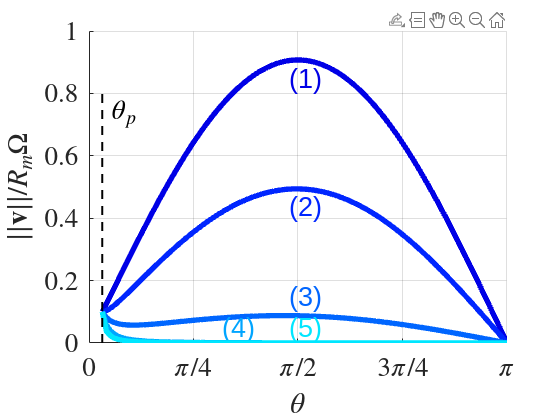

clf
Meshsize=100;
Mesh=linspace(0.1,pi,Meshsize);
color_matrix=jet(1000);
colours=color_matrix(floor(linspace(100,350,5)'),:);

hold on
plot(Mesh,epsilon_00001_Flow,'linewidth',4,'color',colours(1,:))
text(1.5,0.85,'(1)','fontsize',20,'color',colours(1,:));

plot(Mesh,epsilon_0001_Flow,'linewidth',4,'color',colours(2,:))
text(1.5,0.44,'(2)','fontsize',20,'color',colours(2,:))

plot(Mesh,epsilon_001_Flow,'linewidth',4,'color',colours(3,:))
text(1.5,0.15,'(3)','fontsize',20,'color',colours(3,:))

plot(Mesh,epsilon_2_Flow,'linewidth',4,'color',colours(4,:))
text(1,0.05,'(4)','fontsize',20,'color',colours(4,:))

plot(Mesh,epsilon_20_Flow,'linewidth',4,'color',colours(5,:))
text(1.5,0.05,'(5)','fontsize',20,'color',colours(5,:))

%xline(0.1,'--','linewidth',1.5)
plot([0.1, 0.1],[0, 0.8],'--','linewidth',1.5,'color','black')
text(0.15,0.74,'$$\theta_p$$','Interpreter','latex','FontSize',20,'color','black')
hold off
xticks(linspace(0,pi,5));
xticklabels({'$$0$$','$$\pi/4$$','$$\pi/2$$','$$3\pi/4$$','$$\pi$$'});
set(gca, 'XTick', xticks, 'XTickLabel', xticklabels)
set(groot,'defaultAxesTickLabelInterpreter','latex');  
xlabel('$$\theta$$','Interpreter','latex','FontSize',20)
ylabel('$$||\mathbf v||/R_m\Omega$$','Interpreter','latex','FontSize',20)
set(gca,'FontSize',20);
grid on

# Figure 5c

Load MobCoeff_Many_k

% Now plot the solution with 45 modes
epsilon_range=flip([200]);
theta_range=0.1:0.1:3.1;
Cap_Comparison=zeros(length(epsilon_range),length(theta_range));

for i=1:length(epsilon_range)
for j=1:length(theta_range)
    j
    t=theta_range(j);
    accuracy=(100*(t>0.35)+200*(t<=0.35)*(t>=0.15)+300*(t<=0.15));
   load(['MobCoeff' num2str(epsilon_range(i)) '_' num2str(theta_range(j)) '_' num2str(accuracy) '.mat']);
    Cap_Comparison(i,j)=MobilityCoefficient;
end
end

j = 1

j = 2

j = 3

j = 4

j = 5

j = 6

j = 7

j = 8

j = 9

j = 10

j = 11

j = 12

j = 13

j = 14

j = 15

j = 16

j = 17

j = 18

j = 19

j = 20

j = 21

j = 22

j = 23

j = 24

j = 25

j = 26

j = 27

j = 28

j = 29

j = 30

j = 31

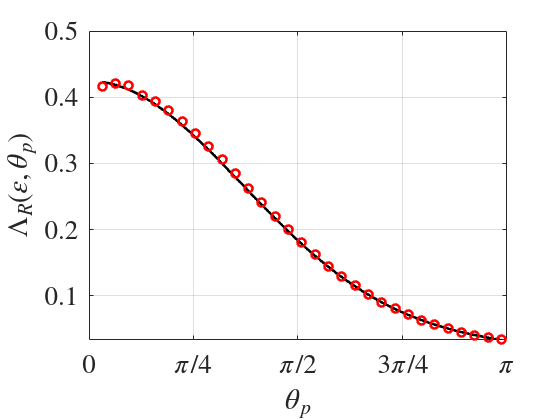

clf
plot(linspace(min(theta_range),max(theta_range),1000),Collins(linspace(min(theta_range),max(theta_range),1000)),'color','black','linewidth',2)
hold on
xlim([0 pi])
scatter(theta_range,Cap_Comparison,'MarkerEdgeColor','red','linewidth',2)
xlabel('$$\theta_p$$', 'Interpreter','latex','fontsize', 20)
ylabel('$$\Lambda_R(\varepsilon,\theta_p)$$','Interpreter','latex','fontsize', 15)
xticks(linspace(0,pi,5));
xticklabels({'$$0$$','$$\pi/4$$','$$\pi/2$$','$$3\pi/4$$','$$\pi$$'});
set(gca, 'XTick', xticks, 'XTickLabel', xticklabels)
ax=gca;
ax.FontSize = 20;
hold off
set(gca,'TickLabelInterpreter','latex')
grid on
ylim([min(Collins(linspace(min(theta_range),max(theta_range),1000))),0.5])

# Compute the V_n

syms x x_c

N_Modes=300;
V_n = sym('V',[1 N_Modes],'real'); % i-th component is v_i(x)
V_n(1)=1/(3*(1-x))-log(1-x)/3; 

for i=2:N_Modes
    i
    A=sym(diag(-(1:i-1).*(4:i+2),-1)+diag((2:i).*(1:i-1),1));
    A=A(:,1:i-1);
    V_n(i)=x*poly2sym(flip(linsolve(A,flip(coeffs(diff(legendreP(i,x),x),'All'))'))');
end
filename=['V_n_' num2str(N_Modes) '.mat'];
save(filename,'V_n');

# Compute IntegralMatrix

N_Modes=300;
Hard_Integrals=sym('H',[1,N_Modes],'real');

syms x x_c

syms numerical_factor
Hard_Integrals(1:3)=int(log(1-x)*(1-x^2)*legendreP(0:2,x),x,[-1,x_c]);

numerical_factor=sym(48);
for i=4:N_Modes  
    i
p=-((x^2-1)*diff((x^2-1)^(i-1),x,i-2)-2*x*diff((x^2-1)^(i-1),x,i-3)+2*diff((x^2-1)^(i-1),x,i-4))/(numerical_factor);
[r,q]=polynomialReduce(p,x-1);
Hard_Integrals(i)=-int(q,x,[-1 x_c])+subs(p*log(1-x),x,x_c)-subs(p*log(1-x),x,-1);
numerical_factor=2*i*numerical_factor;
end

vector=int(legendreP(0:N_Modes-1,x)*(1-x^2),x,[-1 x_c]); % This corresponds to v_0
filename=['IntegralMatrix_' num2str(1)];
save(filename,'vector')

vector=sym('v',[1,N_Modes],'real');

for i=1:N_Modes
   i
vector(i)=1/3*int((1+x)*legendreP(i-1,x),x,[-1 x_c])-1/3*Hard_Integrals(i);
end

filename=['IntegralMatrix_' num2str(2)];
save(filename,'vector')

for i=2:N_Modes
    i
vector=int(V_n(i)'*legendreP(0:N_Modes-1,x)*(1-x^2),x,[-1 x_c]);
filename=['IntegralMatrix_' num2str(i+1)];
save(filename,'vector')
end

syms x x_c
IntegralMatrix_new(1,:)=int(diff(legendreP(1:N_Modes,x),x)*(1-x^2),x,[-1 x_c]); % This corresponds to v_0
IntegralMatrix_new(3:end,:)=int(V_n(2:end)'*diff(legendreP(1:N_Modes,x),x)*(1-x^2),x,[-1 x_c]);
assume(x_c>-1 & x_c<1)
for i=1:N_Modes
    i
 IntegralMatrix_new(2,i)= int(V_n(1)*diff(legendreP(i,x),x)*(1-x^2),x,[-1 x_c]);  
end

# Compute CapIntegrals and TorqueIntegrals

syms x x_c
N_Modes=300;
CapIntegrals=int(legendreP(0:N_Modes-1,x)*(1-x^2), [x_c 1]);

function y=Collins(x)
y=(8*x-4*sin(2*x)+16*sin(x).^3/3)./(8*pi*x.^3);
end